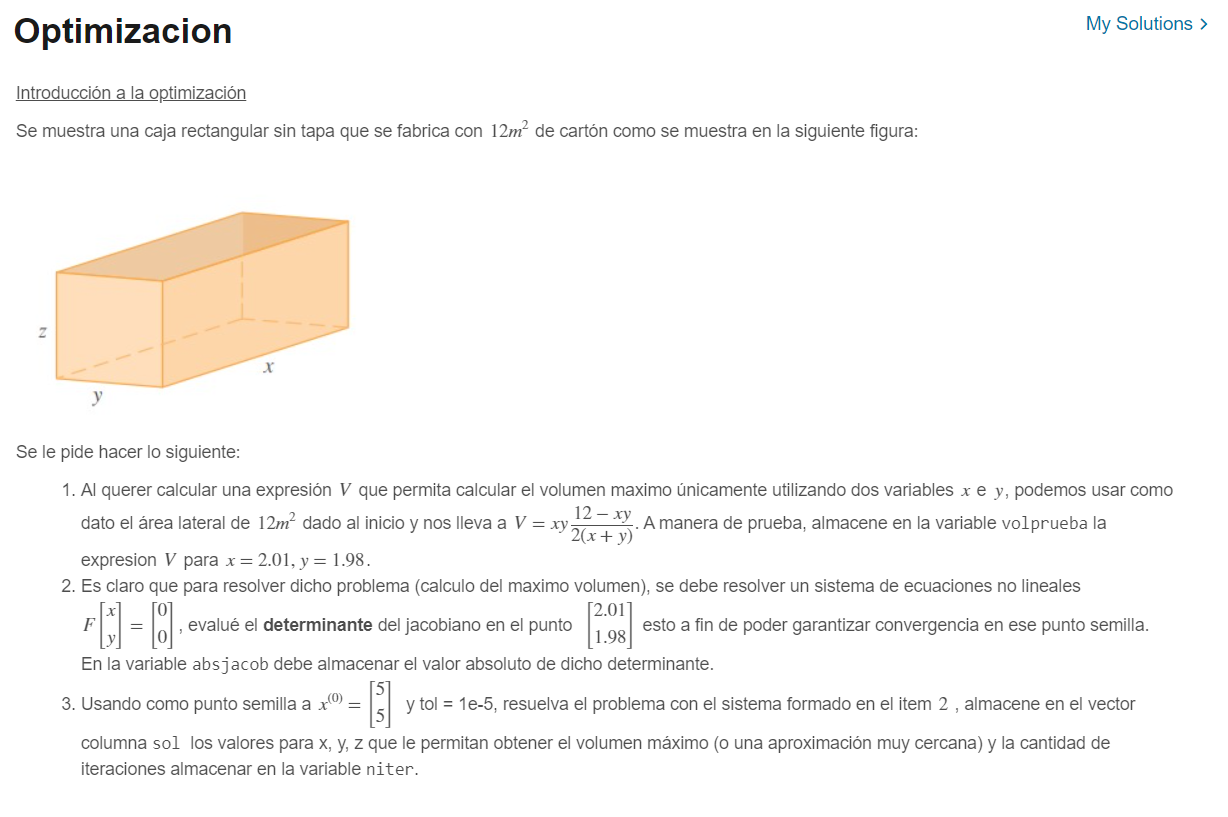

syms x y
V = x*y*(12-x*y)/(2*(x+y));
V = matlabFunction(V)

V = function_handle with value:
    @(x,y)-(x.*y.*(x.*y-1.2e+1))./(x.*2.0+y.*2.0)


volprueba = V(2.01,1.98)

volprueba =    3.999848616541354


J = jacobian(V(x,y),[x y]);
J = matlabFunction(J)

J = function_handle with value:
    @(x,y)[-(x.*y.^2)./(x.*2.0+y.*2.0)-(y.*(x.*y-1.2e+1))./(x.*2.0+y.*2.0)+x.*y.*1.0./(x.*2.0+y.*2.0).^2.*(x.*y-1.2e+1).*2.0,-(x.^2.*y)./(x.*2.0+y.*2.0)-(x.*(x.*y-1.2e+1))./(x.*2.0+y.*2.0)+x.*y.*1.0./(x.*2.0+y.*2.0).^2.*(x.*y-1.2e+1).*2.0]


absjacob = J(2.01,1.98)

absjacob =    0.000036938210187   0.015226411894398
